%real matlab this time

syms s K
Gs = (s+2/3)/(s^2*(s+6));
Hs = 1;
%open loop Ts
Ts = K * Gs *Hs;

pretty(Ts)

  /     2 \
K | s + - |
  \     3 /
-----------
  2
 s  (s + 6)



[num,den] = numden(Gs);
num = sym2poly(num);
den = sym2poly(den);
sys = tf(num,den)


sys =
 
     3 s + 2
  --------------
  3 s^3 + 18 s^2
 
Continuous-time transfer function.
Model Properties


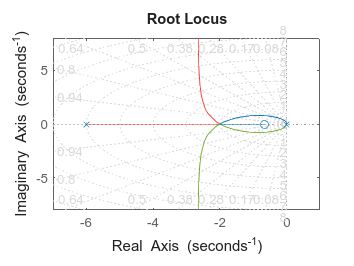


rlocus(sys);
grid on;

Now we're gonna Find the breakaway/breakin oints, the angle between the root locus and the real axis, and the gains at the points.

eqn1 = K == -1*Gs

$$eqn1 = K=-\frac{s+\frac{2}{3}}{s^{2}\,\left(s+6\right)}$$

eqn2 = simplify(diff(eqn1, s))

$$eqn2 = s=-2$$


breakPoints = subs(eqn2, K, 0)

$$breakPoints = s=-2$$

brekaPoints = solve(breakPoints, s)

$$brekaPoints = -2$$

Question 2:

Gs = ((s-2)*(s-3))/ (s*(s+2)*(s+3))

$$Gs = \frac{\left(s-2\right)\,\left(s-3\right)}{s\,\left(s+2\right)\,\left(s+3\right)}$$

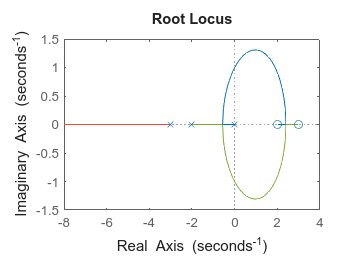

[GsNum,GsDen] = numden(Gs);
GsNum= sym2poly(GsNum);
GsDen= sym2poly(GsDen);
sys = tf(GsNum,GsDen);

rlocus(sys)

Question 3:

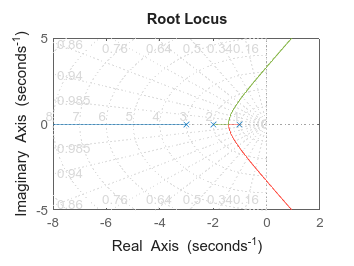

GsDen = ((s+1)*(s+2)*(s+3));
GsNum = 1;
GsDen = sym2poly(GsDen);

sys = tf(GsNum, GsDen);
rlocus(sys);
sgrid(0.5,0);

snake_wn = -0.873

snake_wn = -0.8730

tpThing= 1.68

tpThing = 1.6800

3c ~ Ts and Tp

real = -0.873;
imag = 1.68;
Ts = 4/real

Ts = -4.5819

Tp = pi / imag

Tp = 1.8700

Question 3d: what are the higher order poles

Gs = K *GsNum/((s+1)*(s+2)*(s+3));
Ts = Gs/ (1+Gs);
Rs = 1/s;
Cs = simplify(Rs*Ts)

$$Cs = \frac{K}{s\,\left(s^{3}+6\,s^{2}+11\,s+K+6\right)}$$

Cs = simplify(subs(Cs, K, 9.19))

$$Cs = \frac{919}{100\,s\,\left(s^{3}+6\,s^{2}+11\,s+\frac{1519}{100}\right)}$$


vpa(poles(Cs))

$$ans = \left(\begin{array}{c} -0.87326278504559255317369306264455-1.6758908838852378329026902480914\,\mathrm{i}\\ -0.87326278504559255317369306264455+1.6758908838852378329026902480914\,\mathrm{i}\\ -4.2534744299088148936526138747109\\ 0 \end{array}\right)$$


Ct = ilaplace(Cs,s)

$$Ct = \begin{array}{l} \frac{919}{1519}-\frac{91900\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{s\,\sigma_{2}}\,{\sigma_{2}}^{2}}{\sigma_{1}}\right)}{1519}-\frac{1010900\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{s\,\sigma_{2}}}{\sigma_{1}}\right)}{1519}-\frac{551400\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{2}\,s}\,\sigma_{2}}{100\,\left(12\,\sigma_{2}+3\,{\sigma_{2}}^{2}+11\right)}\right)}{1519}\\ \mathrm{where}\\ \sigma_{1}=100\,\left(3\,{\sigma_{2}}^{2}+12\,\sigma_{2}+11\right)\\ \sigma_{2}=\mathrm{root}\left(z^{3}+6\,z^{2}+11\,z+\frac{1519}{100},z,k\right) \end{array}$$

plot(Ct,linspace(0,5,100))

Error using plot
Data must be numeric, datetime, duration, categorical, or an array convertible to double.

Question 4:

Gs = ((s+2)*(s+3))/((s^2+2*s+2)*(s+4)*(s+5)*(s+6));
[num,den] = numden(Gs)

$$num = \left(s+2\right)\,\left(s+3\right)$$

$$den = \left(s+4\right)\,\left(s+5\right)\,\left(s+6\right)\,\left(s^{2}+2\,s+2\right)$$

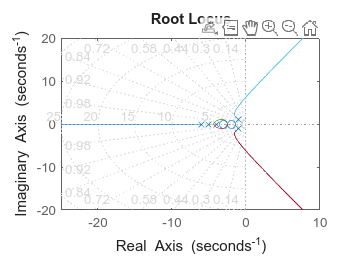

num = sym2poly(num);
den = sym2poly(den);
sys = tf(num,den);
rlocus(sys);
sgrid(0.5,0);

part d

theta1= 180 + atan(1/6)+atan(1/5)+atan(1/4)-atan(1/3)-atan(1/2)+90

theta1 = 269.8221